clc
clear
close

%% Load data


load('spiralwaves.mat')
% "u", "v" are the concentrations of species 1 and 2.
% simulation runs in "t"
% grid resolution in "n"
% x,y,L -- domain information

% know your data
disp(size(u))

    64    64   801



disp(size(v))

    64    64   801



disp(size(t))

   801     1



disp(n^2)

        4096



## Visualize your data

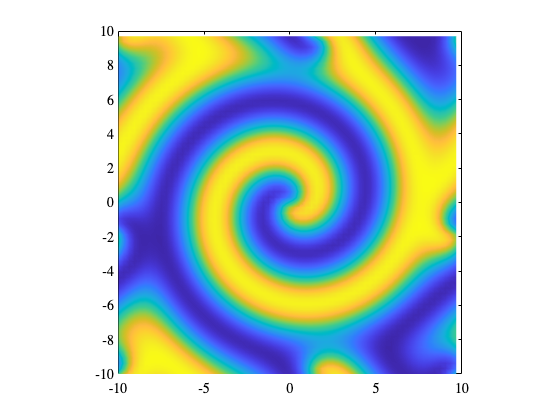

for j = 1:2:length(tspan)
    pcolor(x, y, u(:,:,j))
    shading interp
    legend off
    axis equal
    xlim([-L/2 L/2])
    ylim([-L/2 L/2])

    pause(0.1)
end

## Prepare data

u = reshape(u,n^2,length(tspan));
v = reshape(v,n^2,length(tspan));
F = [u; v]; % data matrix

## Apply SVD

[U, S, V] = svd(F,'econ');

size(U)

ans =         8192         801


size(S)

ans =    801   801


size(V)

ans =    801   801


## Assess the energy content

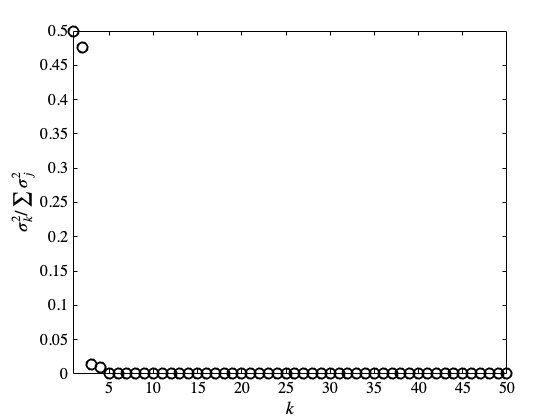

plot(diag(S.^2)/sum(diag(S.^2)),'ko','MarkerSize',10)
xlabel('$k$','interpreter','latex','FontWeight','Bold')
ylabel('$\sigma_k^2/\sum\sigma_j^2$','interpreter','latex','FontWeight','Bold')
set(gca,'Fontsize',16,'Xlim',[0.9 50])

## Finding the POD modes

% First three POD modes
pod1 = reshape(U(1:n^2,1),n,n);
pod2 = reshape(U(1:n^2,2),n,n);
pod3 = reshape(U(1:n^2,3),n,n);


## Plotting the modes

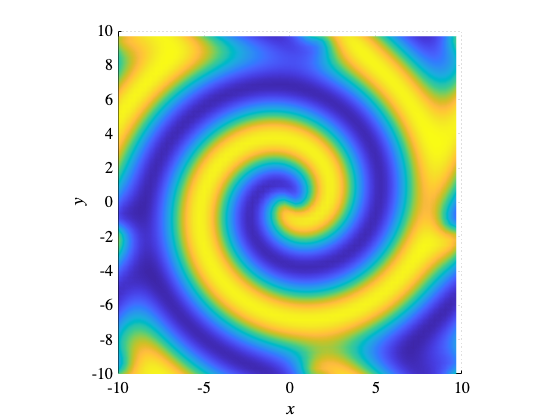

% Plot mode 1
surf(X,Y,pod1)
view(0,90)
axis equal
xlim([-L/2 L/2])
ylim([-L/2 L/2])
shading interp
xlabel('$x$','interpreter','latex','FontWeight','Bold')
ylabel('$y$','interpreter','latex','FontWeight','Bold')
set(gca,'Fontsize',16)

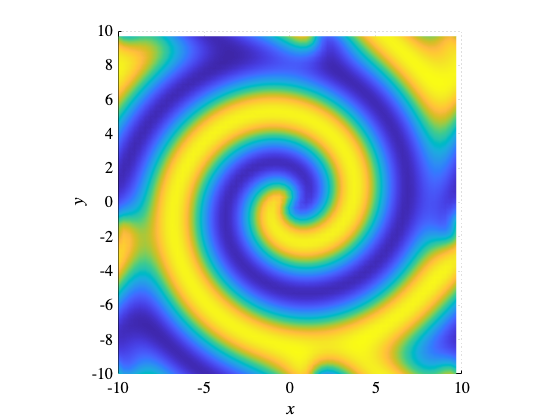

% Plot mode 2
surf(X,Y,pod2)
view(0,90)
axis equal
xlim([-L/2 L/2])
ylim([-L/2 L/2])
shading interp
xlabel('$x$','interpreter','latex','FontWeight','Bold')
ylabel('$y$','interpreter','latex','FontWeight','Bold')
set(gca,'Fontsize',16)

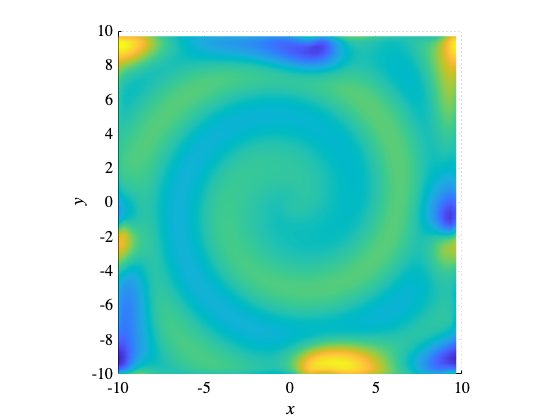

% Plot mode 3
surf(X,Y,pod3)
view(0,90)
axis equal
xlim([-L/2 L/2])
ylim([-L/2 L/2])
shading interp
xlabel('$x$','interpreter','latex','FontWeight','Bold')
ylabel('$y$','interpreter','latex','FontWeight','Bold')
set(gca,'Fontsize',16)

## Finding the temporal modes

% First 3 temporal modes
a1 = V(:,1);
a2 = V(:,2);
a3 = V(:,3);


## Plot time evolution of POD modes

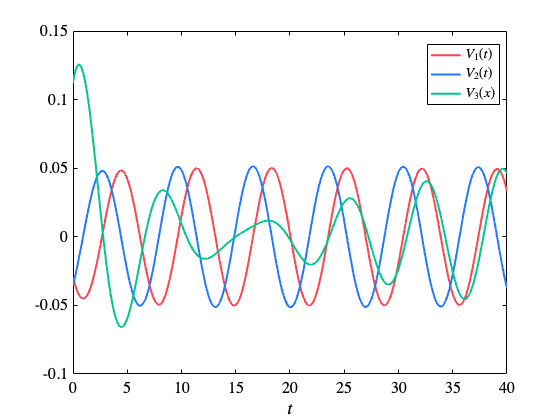

% Plot modes
plot(tspan,a1,'Color',[1 69/255 79/255],'LineWidth',2)
hold on
plot(tspan,a2,'Color',[36/255 122/255 254/255],'LineWidth',2)
plot(tspan,a3,'Color',[0 200/255 140/255],'LineWidth',2)
xlabel('$t$','interpreter','latex','FontWeight','Bold')
legend('$V_1(t)$','$V_2(t)$','$V_3(x)$','Location','Best','interpreter','latex')
set(gca,'Fontsize',16,'Xlim',[0 40])

## Reconstructing the fields

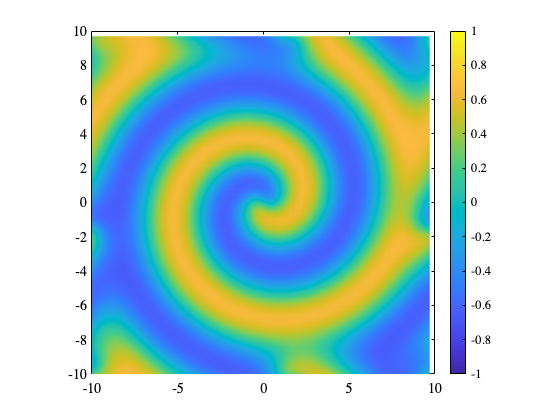

r=1;
Ftilde = U(:,1:r) * S(1:r,1:r) * V(:,1:r)';
figure
for i = 1:1:numel(tspan)
    pcolor(x, y, reshape(Ftilde(1:end/2,i),n,n))
    shading interp
    clim([-1 1])
    axis equal
    xlim([-L/2 L/2])
    ylim([-L/2 L/2])
    colorbar
    pause(0.1)
end